# Horizontal displacement code

## Import data (from camera 1)

%%% Imports data
Dataset_Hor = 'Horizontal Displacement';
Camera_Hor = 'cam1_3.mat';

camData_Hor = importCamData(Dataset_Hor,Camera_Hor);


## Camera 1

### Shows uncropped and cropped frame in colour

%%% Shows uncropped and cropped frame in colour
frame_Hor = 1

frame_Hor = 1

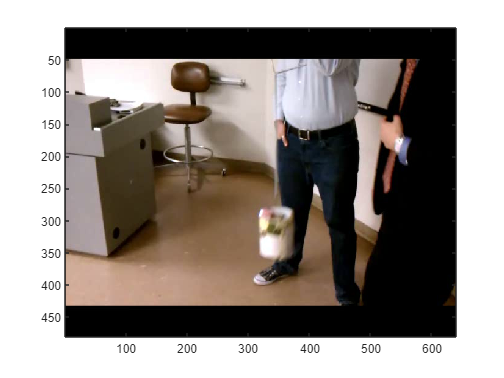


camImage_Hor = image(camData_Hor.vidFrames1_3(:,:,:,frame_Hor));

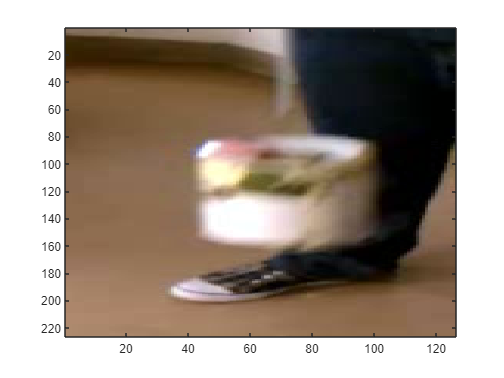

width_Hor = 275:400;
height_Hor = 200:425;
croppedFrame_Hor = camData_Hor.vidFrames1_3(height_Hor,width_Hor,:,frame_Hor);
croppedFrame1_Hor = camData_Hor.vidFrames1_3(height_Hor,width_Hor,:,1);
camImageCropped_Hor = image(croppedFrame_Hor);

### Shows frame of grayscale image

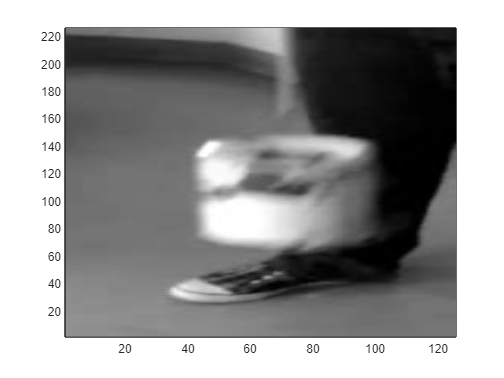

%%% Shows a frame from any camera as a grayscale colourmap (to locate
%%% locations of particular points

%%% Modified from: Data-Driven Modeling & Scientific Computation: 
%%% Methods for Complex Systems & Big Data 
%%% by J. NATHAN KUTZ


a_Hor = flipud( double( rgb2gray( camData_Hor.vidFrames1_3(height_Hor,width_Hor,:,1) )));
% a_Hor = flipud( double( rgb2gray( camData_Hor_2.vidFrames2_3(height_Hor_2,width_Hor_2,:,1) )));
% a_Hor = flipud( double( rgb2gray( camData_Hor_3.vidFrames3_3(height_Hor_3,width_Hor_3,:,1) )));

% x = 1:640;
% y = 1:480;
% [X,Y]=meshgrid(x,y);
% pcolor(X,Y,a)
pcolor(a_Hor)
shading interp
colormap("gray")

% set(gca,'Xtick',[],'Ytick',[],'Ztick',[])


### Finds and shows cap pixels (using both methods)

%%% Finds and shows cap pixels
x_Hor = 47;
y_Hor = 137;


r_Hor = croppedFrame1_Hor(end-y_Hor,x_Hor,1)

r_Hor = uint8
255

g_Hor = croppedFrame1_Hor(end-y_Hor,x_Hor,2)

g_Hor = uint8
255

b_Hor = croppedFrame1_Hor(end-y_Hor,x_Hor,3)

b_Hor = uint8
251

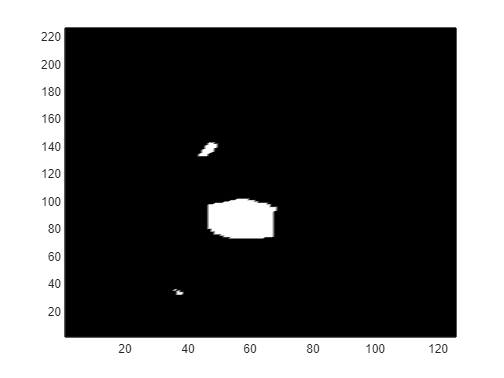


d_Hor = 20;
cap_Pixels_Hor = ((croppedFrame_Hor(:,:,1) >= r_Hor - d_Hor) & (croppedFrame_Hor(:,:,1) <= r_Hor + d_Hor)) ...
            &((croppedFrame_Hor(:,:,2) >= g_Hor - d_Hor) & (croppedFrame_Hor(:,:,2) <= g_Hor + d_Hor)) ...
            &((croppedFrame_Hor(:,:,3) >= b_Hor - d_Hor) & (croppedFrame_Hor(:,:,3) <= b_Hor + d_Hor));

pcolor(flipud(cap_Pixels_Hor))
shading interp
colormap("gray")

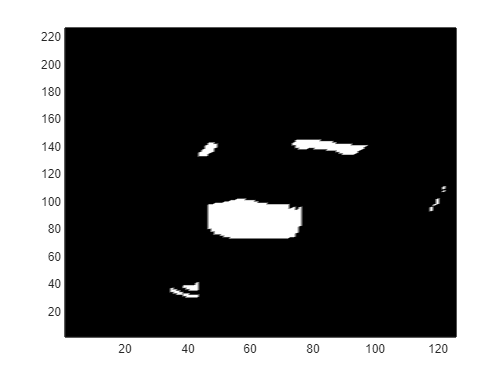


cap_Pixels_Hor_2 = getCapPixelsBright(croppedFrame_Hor,d_Hor);

pcolor(flipud(cap_Pixels_Hor_2))
shading interp
colormap("gray")

### Finds x and y coordinate of average of cap pixels

%%% Finds x and y coordinate of average of cap pixels
bounds_Hor = Boundaries(cap_Pixels_Hor)

bounds_Hor = 141

[top_Hor,bottom_Hor,left_Hor,right_Hor] = Boundaries(cap_Pixels_Hor)

top_Hor = 141

bottom_Hor = 31

left_Hor = 36

right_Hor = 68


[x_Hor,y_Hor] = centre(top_Hor,bottom_Hor,left_Hor,right_Hor)

x_Hor = 52

y_Hor = 86

[x_avg_Hor,y_avg_Hor] = centre_avg(cap_Pixels_Hor)

x_avg_Hor = 56.5052

y_avg_Hor = 87.8690

### Finds position of cap and stores it into a vector

%%% Finds position of cap and stores it into a vector
numFrames_Hor = size(camData_Hor.vidFrames1_3(1,1,1,:),4);
% width_Hor = 275:400;
% height_Hor = 200:425;
croppedFrame1_Hor = camData_Hor.vidFrames1_3(height_Hor,width_Hor,:,1);

x_Hor = 47;
y_Hor = 137;
d_Hor = 20;

X_0_Hor = zeros(1,numFrames_Hor);
Y_0_Hor = zeros(1,numFrames_Hor);

for i = 1:numFrames_Hor
    croppedFrame_Hor = camData_Hor.vidFrames1_3(height_Hor,width_Hor,:,i);
    cap_Pixels_Hor = getCapPixels(croppedFrame1_Hor,croppedFrame_Hor,x_Hor,y_Hor,d_Hor);
    
    [x_avg_Hor,y_avg_Hor] = centre_avg(cap_Pixels_Hor);
    X_0_Hor(i) = x_avg_Hor;
    Y_0_Hor(i) = y_avg_Hor;
end

X_0_Hor

X_0_Hor =    56.5052   56.5052   56.5838   56.5525   56.5412   56.5412   56.5412   51.6720   51.7018   48.0658   48.1144   45.8605   45.9503   42.2491   42.1788   39.9282   39.8991   37.5409   37.6680   35.2917   33.6543   33.9026   32.5976   32.5746   32.6953   32.7539   33.1304   33.6981   33.6556   35.3342   35.3026   35.8750   36.1368   38.5097   41.4837   41.3090   43.8043   43.8616   45.8241   45.8739   47.1022   48.0652   48.2170   48.6934   48.7529   50.1274   50.1493   51.1151   53.2686   53.1761


Y_0_Hor

Y_0_Hor =    87.8690   87.8690   87.9136   87.8950   87.9107   87.9107   87.9107   79.3656   79.3893   73.4718   73.5310   71.5474   71.5417   69.0091   68.9343   69.0772   69.2288   71.3405   71.4214   75.9978   81.0232   81.2831   87.0122   86.9462   93.3958   93.4352  100.9837  108.8670  108.7361  115.9421  116.1316  123.1372  123.1094  129.6787  135.3333  135.3141  136.1790  136.1193  136.1114  135.9956  131.2111  123.4315  123.6488  113.9085  114.0412  102.4764  102.4787   89.2734   77.2099   77.1287


### Plots X and Y for camera 1

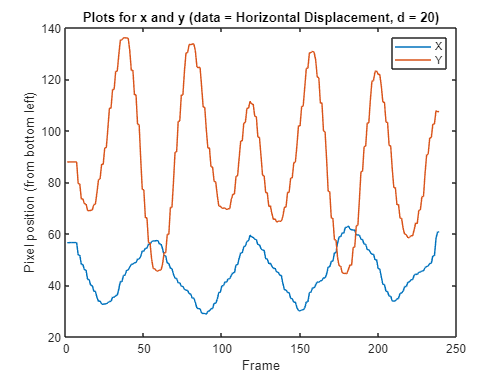

%%% Plots X and Y
plot(X_0_Hor)
title('Plots for x and y (data = Horizontal Displacement, d = 20)')
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y_0_Hor)
legend('X','Y')
hold off

### Finds and plots X and Y for camera 1 for any d (with function that uses initial position)

%%% Finds and plots X and Y for any d (with function)
% width_Hor = 275:400;
% height_Hor = 200:425;
x_Hor = 47;
y_Hor = 137;
d1_Hor = 50;

[X_11_Hor,Y_11_Hor] = getXY(camData_Hor.vidFrames1_3,width_Hor,height_Hor,x_Hor,y_Hor,d1_Hor)

X_11_Hor =    59.0813   59.0929   58.9819   58.9811   59.0262   58.9946   59.0180   55.2663   55.2455   51.4776   51.4734   47.8650   47.8691   44.3046   44.3064   41.9047   41.8514   39.9463   39.9474   37.3961   36.3212   36.3750   35.8914   35.8687   36.6557   36.6688   37.7246   38.7251   38.6636   40.4809   40.4404   42.2843   42.3556   43.8442   45.0904   45.1235   47.4471   47.4024   48.8909   48.9544   50.5953   52.1815   52.1641   52.8380   52.7631   54.2385   54.2683   55.4941   56.9038   56.9795


Y_11_Hor =    93.8462   93.8257   93.5149   93.5953   93.4919   93.5671   93.5239   86.8302   86.7089   80.6922   80.7283   76.7886   76.7224   74.1121   73.9528   74.9394   74.6902   76.1560   76.1992   79.0204   84.2388   84.3915   90.4704   90.4172   97.2313   97.2322  104.7246  112.2552  112.1051  120.3564  120.1960  126.1443  126.1509  131.7096  135.7411  135.5391  137.2698  137.3447  135.9289  136.0608  132.5124  125.7447  125.3927  115.8431  115.7083  104.7731  104.8023   92.9201   80.6936   80.7009


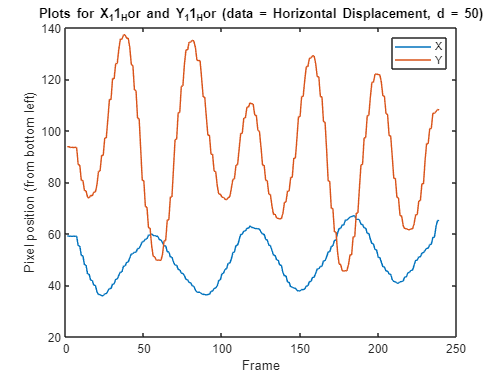

% X_11_Hor = X_11_Hor+width_Hor(1);
% Y_11_Hor = Y_11_Hor+height_Hor(1);

plotXY(X_11_Hor,Y_11_Hor,d1_Hor,Dataset_Hor)

### Finds and plots X and Y for camera 1 for any d (with function that uses brightness)

%%% Finds and plots X and Y for any d (with function)
% width_Hor = 275:400;
% height_Hor = 200:425;
d2_Hor = 50;

[X_12_Hor,Y_12_Hor] = getXYBright(camData_Hor.vidFrames1_3,width_Hor,height_Hor,d2_Hor)

X_12_Hor =    61.1692   61.7990   61.9129   61.7836   61.7026   61.7004   61.7939   60.8957   60.8789   59.4481   59.4711   59.4238   59.2515   59.6148   59.4347   59.2148   58.7783   57.4305   57.4273   59.6496   62.0911   62.2137   63.7019   63.8847   65.5151   65.5658   65.0740   64.4355   63.9873   63.1635   63.3967   62.6932   62.7761   61.9625   60.8636   60.7416   59.8043   59.7569   60.8593   60.7612   60.8958   61.6928   61.6820   62.7655   62.7336   62.5729   62.3078   62.7428   61.7627   62.1241


Y_12_Hor =    60.1669   59.8753   59.7647   59.8294   59.7333   59.8483   59.9127   59.5807   59.5098   58.3795   58.1867   51.4631   51.4161   50.9701   51.0138   55.0333   55.3753   62.6545   62.1952   64.4851   65.2807   65.0876   66.0508   65.9154   65.6327   65.6200   66.5151   66.9313   67.0151   68.2023   68.0415   66.2753   66.4725   65.4328   65.2191   65.4831   64.8174   65.0915   64.1152   64.0060   64.9623   65.0320   64.8752   65.6818   65.4301   63.9770   63.8144   61.5060   59.4461   59.3501


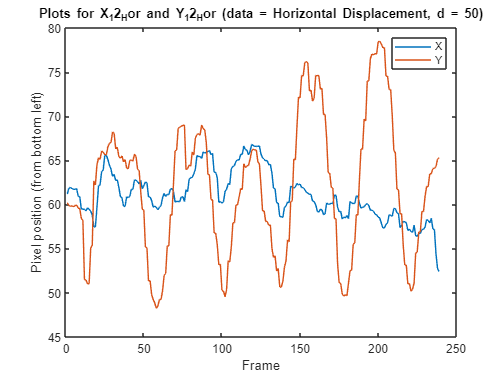


plotXY(X_12_Hor,Y_12_Hor,d2_Hor,Dataset_Hor)

## Camera 2

### Imports data

%%% Imports data from second camera
Camera_Hor_2 = 'cam2_3.mat';

camData_Hor_2 = importCamData(Dataset_Hor,Camera_Hor_2);


### Shows uncropped and cropped frame in colour

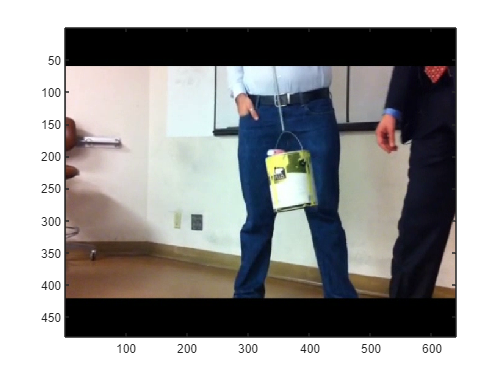

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_Hor_2 = 25;

camImage_Hor_2 = image(camData_Hor_2.vidFrames2_3(:,:,:,frame_Hor_2));

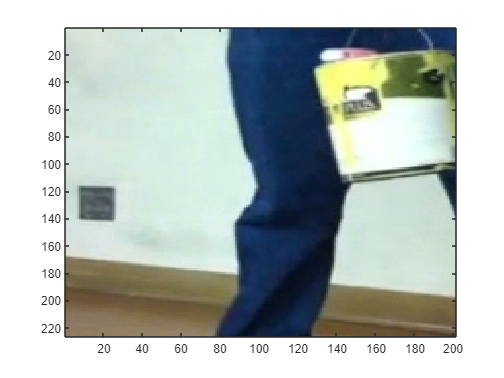

width_Hor_2 = 200:400;
height_Hor_2 = 175:400;
croppedFrame_Hor_2 = camData_Hor_2.vidFrames2_3(height_Hor_2,width_Hor_2,:,frame_Hor_2);
camImageCropped_Hor_2 = image(croppedFrame_Hor_2);

### Finds and plots X and Y for camera 2 (using initial position)

%%% Finds and plots X and Y for camera 2
% width_Hor_2 = 200:400;
% height_Hor_2 = 175:400;
x_Hor_2 = 39;
y_Hor_2 = 109;
d1_Hor_2 = 50;

[X_21_Hor,Y_21_Hor] = getXY(camData_Hor_2.vidFrames2_3,width_Hor_2,height_Hor_2,x_Hor_2,y_Hor_2,d1_Hor_2)

X_21_Hor =    73.1185   72.7731   72.7493   73.0289   73.5307   74.1251   73.9504   75.1584   75.3257   74.3450   72.1857   72.1629   70.4957   70.6496   71.9943   75.0449   75.0687   77.9689   80.4088   82.3074   83.8665   83.7862   84.8218   82.5624   80.6004   79.9119   79.8702   79.2505   78.4429   77.5196   75.9911   74.1736   72.3658   70.7343   68.4118   68.4426   67.4013   67.3470   66.7513   66.9298   69.1552   68.0473   66.6706   66.4114   66.6300   65.8507   64.6807   64.7275   65.2531   63.4642


Y_21_Hor =   123.9791  124.0828  122.3245  121.5464  120.9298  121.4135  121.4481  121.5071  121.6725  122.6053  124.3438  124.4014  126.2313  126.4711  126.4239  125.7909  125.7776  125.2958  125.2573  125.5713  126.3203  126.3166  126.6608  127.1093  128.3257  129.3943  129.3919  130.1086  130.3836  130.0715  131.5521  130.7676  129.8522  128.9212  127.4968  127.5301  126.5309  124.4140  123.4681  122.3298  121.2299  121.6239  122.5322  122.2504  121.9369  122.2459  123.0645  123.4197  124.2461  126.3828


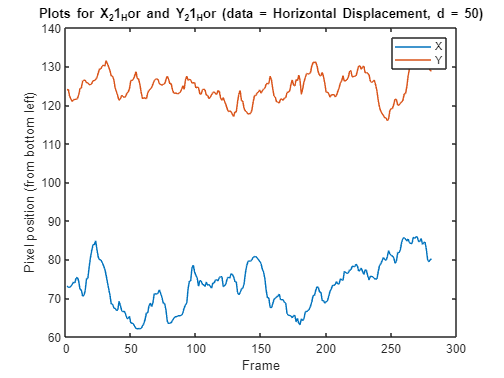


plotXY(X_21_Hor,Y_21_Hor,d1_Hor_2,Dataset_Hor)

### Finds and plots X and Y for camera 2 (using brightness)

%%% Finds and plots X and Y for camera 2
% width_Hor_2 = 200:400;
% height_Hor_2 = 175:400;
d2_Hor_2 = 50;

[X_22_Hor,Y_22_Hor] = getXYBright(camData_Hor_2.vidFrames2_3,width_Hor_2,height_Hor_2,d2_Hor_2)

X_22_Hor =    92.3617   92.3456   91.1277   89.9865   88.1544   86.1207   86.0987   86.4300   86.8176   86.3968   83.8226   83.7982   81.6324   79.9302   78.7380   80.1921   80.1707   83.4983   86.7946   89.2470   91.4761   91.4424   92.5971   92.4416   92.2165   91.6161   91.6331   90.5684   89.3388   86.7965   86.7989   83.7255   81.2822   80.4301   80.9351   80.9473   81.8015   83.5013   84.6107   85.6056   85.8077   85.8151   85.5922   85.3186   85.0342   85.0235   85.5241   86.6261   87.6845   88.2810


Y_22_Hor =   121.7462  121.7613  120.4272  120.1212  119.8733  120.3597  120.4249  120.3122  120.5821  120.9556  123.1909  123.2300  125.2245  125.7900  125.3501  124.2989  124.2708  123.2070  122.7109  122.7047  123.3688  123.3634  123.4458  123.2527  123.6334  124.2982  124.2724  125.0825  125.4805  125.6311  125.7000  125.4736  125.5667  125.9207  124.7490  124.7476  123.8296  122.5006  120.9512  119.3174  119.8715  119.8720  120.2881  119.6757  119.4325  119.4778  119.5247  119.8293  120.4823  120.9173


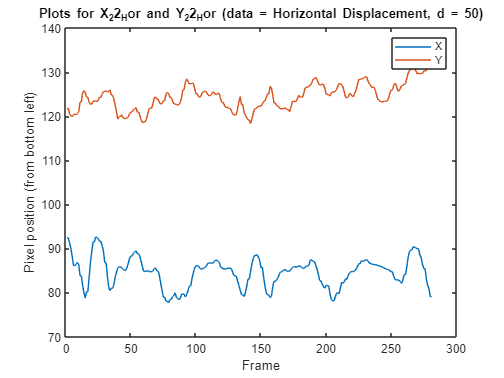


plotXY(X_22_Hor,Y_22_Hor,d2_Hor_2,Dataset_Hor)

## Camera 3

### Import data

%%% Imports data from third camera
Camera_Hor_3 = 'cam3_3.mat';

camData_Hor_3 = importCamData(Dataset_Hor,Camera_Hor_3);


### Shows uncropped and cropped frame in colour

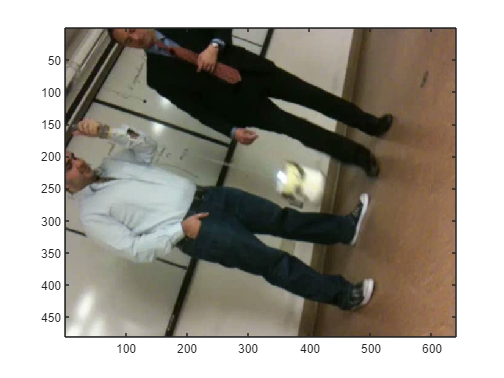

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_Hor_3 = 1;

camImage_Hor_3 = image(camData_Hor_3.vidFrames3_3(:,:,:,frame_Hor_3));

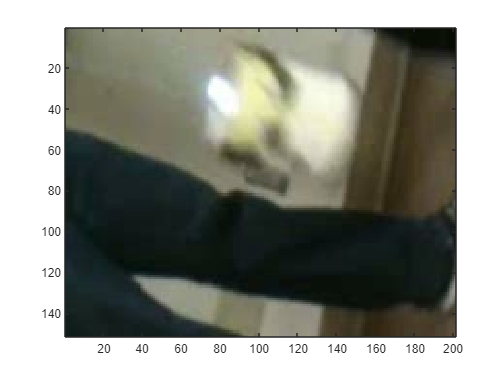

width_Hor_3 = 275:475;
height_Hor_3 = 200:350;
croppedFrame_Hor_3 = camData_Hor_3.vidFrames3_3(height_Hor_3,width_Hor_3,:,frame_Hor_3);
camImageCropped_Hor_3 = image(croppedFrame_Hor_3);

### Finds and plots X and Y for camera 3 (using initial position)

%%% Finds and plots X and Y for camera 3
% width_Hor_3 = 275:475;
% height_Hor_3 = 200:350;
x_Hor_3 = 78;
y_Hor_3 = 122;
d1_Hor_3 = 50;

[X_31_Hor,Y_31_Hor] = getXY(camData_Hor_3.vidFrames3_3,width_Hor_3,height_Hor_3,x_Hor_3,y_Hor_3,d1_Hor_3)

X_31_Hor =   116.9649  116.8531  124.3346  124.5567  132.2207  132.2005  136.5973  139.4671  139.4863  139.1299  139.1941  135.4555  135.6215  128.2145  120.3202  120.3059  110.6569  110.5927   99.9043  100.0948   88.5460   79.0179   79.2597   70.3285   70.4132   63.7810   63.8685   59.9962   59.0190   59.4374   60.3930   60.2828   62.6891   62.1630   68.2738   75.6020   75.5252   84.1280   84.0037   96.0739   95.7667  107.2639  119.0691  119.1485  128.7823  129.0141  138.2928  138.1363  144.3987  147.7843


Y_31_Hor =   113.1643  113.1690  101.5069  101.4034   90.5578   90.6158   78.6037   69.8194   69.6256   61.2362   61.2789   55.7714   55.7699   52.0789   50.5394   50.5874   51.1490   51.2472   54.6228   54.5310   59.0109   64.4014   64.3336   71.8679   71.8281   78.4857   78.3936   84.6317   90.5976   90.6164   97.2196   97.2611  102.2566  102.2689  107.3019  110.9070  110.9414  114.7178  114.7098  117.8152  117.8490  120.2299  121.9816  121.9899  122.5181  122.5178  123.2326  123.2115  122.9244  123.0575


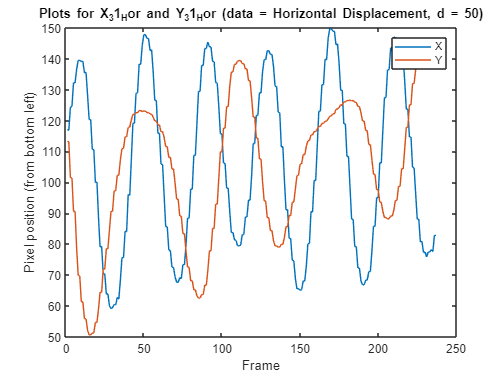


plotXY(X_31_Hor,Y_31_Hor,d1_Hor_3,Dataset_Hor)

### Finds and plots X and Y for camera 3 (using brightness)

%%% Finds and plots X and Y for camera 3
% width_Hor_3 = 275:475;
% height_Hor_3 = 200:350;
d2_Hor_3 = 50;

[X_32_Hor,Y_32_Hor] = getXYBright(camData_Hor_3.vidFrames3_3,width_Hor_3,height_Hor_3,d2_Hor_3)

X_32_Hor =   109.1460  109.2807  106.8813  106.7918  100.2315  100.0622   98.2641   96.5355   96.5382   95.9662   95.8941   97.1083   96.9818   99.4453  103.4173  103.4121  105.2334  105.2131  110.4147  110.3973  114.5319  117.4511  117.5663  119.4584  119.5625  120.5720  120.7271  121.9086  124.1234  124.4383  126.4905  126.7062  126.7392  126.7265  124.9746  120.6675  120.8316  117.5997  117.4156  112.5006  112.5419  106.9379  105.9333  105.9569  102.2565  101.8005   99.0966   99.1227   95.6302   92.9806


Y_32_Hor =   103.4268  103.5010  101.5332  101.5836  100.2834  100.3533   98.0987   96.4901   96.4984   94.5977   94.6612   92.9201   92.8549   91.1906   90.9085   91.0246   92.2742   92.4075   93.9224   93.9171   94.6487   94.6089   94.7093   94.5595   94.5583   95.1874   95.1614   95.3502   94.9584   94.9324   95.6629   95.5948   96.9952   96.8752   98.1089  101.0574  101.0197  103.6822  103.8679  105.6883  105.6380  103.2896  101.0209  100.9196   99.5115   99.4844   99.4850   99.3828   99.0762   99.5984


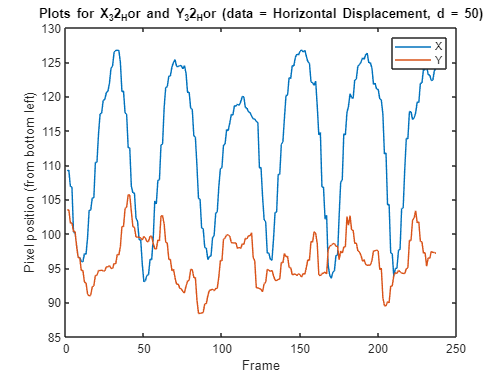


plotXY(X_32_Hor,Y_32_Hor,d2_Hor_3,Dataset_Hor)

## PCA

### Merge cameras' X and Y data

sz_Hor = min( [size(X_11_Hor,2), size(X_21_Hor,2), size(X_31_Hor,2)] )

sz_Hor = 237


X_Hor = cat( 1,X_11_Hor(1:sz_Hor),Y_11_Hor(1:sz_Hor),X_21_Hor(1:sz_Hor),Y_21_Hor(1:sz_Hor),X_31_Hor(1:sz_Hor),Y_31_Hor(1:sz_Hor) )

X_Hor =    59.0813   59.0929   58.9819   58.9811   59.0262   58.9946   59.0180   55.2663   55.2455   51.4776   51.4734   47.8650   47.8691   44.3046   44.3064   41.9047   41.8514   39.9463   39.9474   37.3961   36.3212   36.3750   35.8914   35.8687   36.6557   36.6688   37.7246   38.7251   38.6636   40.4809   40.4404   42.2843   42.3556   43.8442   45.0904   45.1235   47.4471   47.4024   48.8909   48.9544   50.5953   52.1815   52.1641   52.8380   52.7631   54.2385   54.2683   55.4941   56.9038   56.9795
   93.8462   93.8257   93.5149   93.5953   93.4919   93.5671   93.5239   86.8302   86.7089   80.6922   80.7283   76.7886   76.7224   74.1121   73.9528   74.9394   74.6902   76.1560   76.1992   79.0204   84.2388   84.3915   90.4704   90.4172   97.2313   97.2322  104.7246  112.2552  112.1051  120.3564  120.1960  126.1443  126.1509  131.7096  135.7411  135.5391  137.2698  137.3447  135.9289  136.0608  132.5124  125.7447  125.3927  115.8431  115.7083  104.7731  104.8023   92.9201   80.6936 

### Do PCA on the data matrix (using SVD decomposition)

[~,Y_Hor,lambda_Hor] = pca(X_Hor.')

Y_Hor =     6.9940    5.3258   12.4423    4.8352    5.0636    1.7314
    6.9198    5.3699   12.4092    4.9847    4.7287    1.7386
   15.0920   -5.4210   10.0992    7.1077    5.8187    0.7804
   15.2665   -5.6070   10.2102    7.0446    6.3121    0.1283
   23.3140  -15.8205    8.4681    8.8392    7.5752    0.4102
   23.2110  -15.8119    8.4542    8.5416    7.9420    1.0132
   28.6673  -26.3812    4.5582   11.0970    8.3220    1.5822
   35.6543  -31.5250   -3.5292    8.8839    7.9342    1.4651
   35.7500  -31.6285   -3.7265    8.8301    8.0228    1.6622
   39.6741  -36.1497  -12.5770    7.6253    5.3554    1.6547


lambda_Hor =   942.7033
  704.9928
  343.2924
   44.6517
   18.5155
    6.5784


Y_Hor = Y_Hor.'

Y_Hor =     6.9940    6.9198   15.0920   15.2665   23.3140   23.2110   28.6673   35.6543   35.7500   39.6741   39.7202   39.3083   39.4800   35.0285   28.6930   27.9649   19.9460   18.9392    9.4063    7.9084   -5.2653  -14.0908  -17.1401  -25.6135  -29.0528  -35.5790  -39.3794  -47.4394  -49.0314  -52.8955  -52.9734  -56.0252  -54.6496  -57.8574  -55.4183  -49.7136  -50.5204  -43.8499  -43.0916  -33.4908  -31.8582  -18.9461   -9.1322   -4.0037    4.0419   10.0605   17.7116   23.8647   35.5784   38.3800
    5.3258    5.3699   -5.4210   -5.6070  -15.8205  -15.8119  -26.3812  -31.5250  -31.6285  -36.1497  -36.0822  -38.6711  -38.6095  -39.6966  -39.4210  -40.4525  -38.0887  -39.1984  -34.5171  -36.6236  -33.6993  -27.6034  -30.8801  -23.0246  -26.2865  -19.5991  -23.2374  -20.9939  -15.8756  -19.6968  -14.3747  -16.9106  -13.2731  -15.6419  -14.4394  -12.7559  -13.0872  -11.7012  -10.6583  -10.4508   -8.2709   -4.6881   -5.2449   -0.2937   -1.6114    4.1968    3.0785    9.3553   14.4399 

### Plot PCA components 

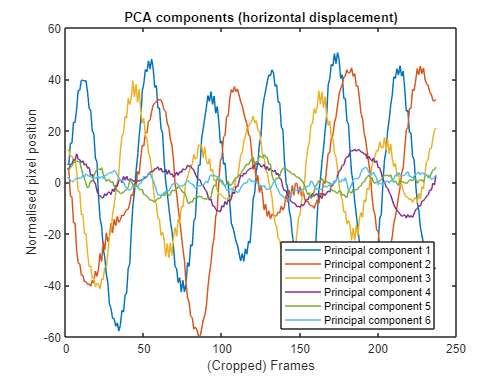

plot(Y_Hor(1,:))
title('PCA components (horizontal displacement)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')

hold on
plot(Y_Hor(2,:))
plot(Y_Hor(3,:))
plot(Y_Hor(4,:))
plot(Y_Hor(5,:))
plot(Y_Hor(6,:))
legend('Principal component 1', ...
       'Principal component 2', ...
       'Principal component 3', ...
       'Principal component 4', ...
       'Principal component 5', ...
       'Principal component 6','Location','best')
hold off

### Plots PCA eigenvalues

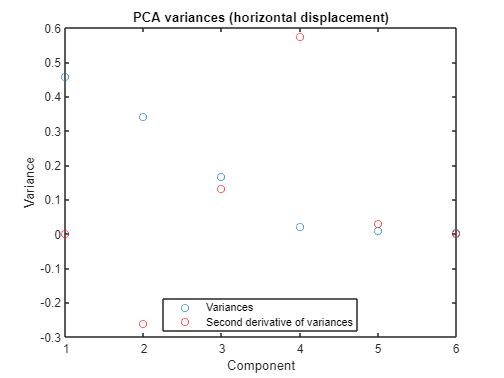

plot(lambda_Hor/sum(lambda_Hor), 'o')
title('PCA variances (horizontal displacement)')
xlabel('Component')
ylabel('Variance')

ddlambda_Hor = zeros(size(lambda_Hor));
for i = 1:length(lambda_Hor)
    if i == 1
        ddlambda_Hor(i) = 0;
    elseif i == length(lambda_Hor)
        ddlambda_Hor(i) = 0;
    else
        ddlambda_Hor(i) = (lambda_Hor(i+1) - 2*lambda_Hor(i) + lambda_Hor(i-1));
    end
end

hold on
plot(ddlambda_Hor/sum(abs(ddlambda_Hor)), 'ro')
legend('Variances','Second derivative of variances','Location','best')
hold off

## Analysis

### Gets fast fourier transforms of largest principal components 

%%% Modified from fft documentation

Fs_Hor = 1;            % Sampling frequency                    
T_Hor = 1/Fs_Hor;             % Sampling period       
L_Hor = sz_Hor;             % Length of signal
t_Hor = (0:L_Hor-1)*T_Hor;        % Time vector

f_1_Hor = fft(Y_Hor(1,:))

f_1_Hor = 	1.0e+03 *

  -0.0000 + 0.0000i  -0.0541 + 0.4015i   0.1776 + 0.5247i   0.1334 + 0.3632i   1.2023 + 0.3256i   0.1217 + 0.1002i  -2.5047 - 4.1631i  -0.0955 - 0.3281i   0.0274 - 0.2443i   0.0195 - 0.1972i  -0.0381 - 0.1579i   0.0224 - 0.1372i  -0.1978 - 0.0857i   0.0005 - 0.0533i   0.0073 - 0.0927i   0.0231 - 0.0802i   0.0130 - 0.0921i   0.0030 - 0.0815i   0.0235 - 0.0603i   0.0138 - 0.0529i  -0.0022 - 0.0829i   0.0368 - 0.0431i   0.0144 - 0.0433i   0.0234 - 0.0408i   0.0192 - 0.0508i   0.0131 - 0.0590i   0.0064 - 0.0474i   0.0052 - 0.0470i   0.0860 - 0.0965i   0.0218 - 0.0420i   0.0106 - 0.0796i   0.0231 - 0.0404i   0.0073 - 0.0318i   0.0094 - 0.0407i   0.0176 - 0.0290i   0.0183 - 0.0273i  -0.0078 - 0.0267i   0.0046 - 0.0197i   0.0108 - 0.0006i   0.0198 + 0.0094i   0.0336 - 0.1565i   0.0244 - 0.0463i   0.0237 - 0.0274i   0.0180 - 0.0212i   0.0232 - 0.0413i   0.0084 - 0.0081i   0.0146 - 0.0328i   0.0162 - 0.0214i   0.0128 - 0.0133i   0.0204 - 0.0303i


f_2_Hor = fft(Y_Hor(2,:))

f_2_Hor = 	1.0e+03 *

   0.0000 + 0.0000i   0.0800 + 1.1554i  -0.3936 + 0.3515i  -0.7666 + 0.5780i   2.7653 + 2.0752i   0.5154 + 0.0768i  -1.2017 + 1.8150i   0.1233 + 0.1711i   0.1017 + 0.0666i   0.0799 + 0.1188i   0.0807 - 0.0170i   0.0778 + 0.0672i  -0.0047 + 0.0298i   0.0326 + 0.0353i   0.0335 + 0.0299i   0.0426 + 0.0280i   0.0374 + 0.0293i   0.0272 + 0.0435i   0.0346 + 0.0342i   0.0220 + 0.0326i   0.0170 + 0.0245i   0.0271 + 0.0197i   0.0077 + 0.0337i   0.0173 + 0.0144i  -0.0011 + 0.0267i  -0.0030 + 0.0098i   0.0044 + 0.0193i   0.0053 + 0.0083i  -0.0193 + 0.0924i   0.0095 + 0.0217i  -0.0458 + 0.0110i  -0.0027 + 0.0239i  -0.0055 + 0.0251i  -0.0160 + 0.0132i  -0.0049 + 0.0253i  -0.0136 + 0.0190i  -0.0103 + 0.0124i  -0.0185 + 0.0100i   0.0042 + 0.0688i   0.0056 + 0.0175i  -0.0204 + 0.0285i  -0.0068 + 0.0134i  -0.0121 + 0.0239i  -0.0077 + 0.0219i  -0.0027 + 0.0099i  -0.0044 + 0.0280i  -0.0056 + 0.0106i  -0.0045 + 0.0109i  -0.0073 + 0.0242i   0.0049 + 0.0160i


f_3_Hor = fft(Y_Hor(3,:))

f_3_Hor = 	1.0e+03 *

   0.0000 + 0.0000i  -0.2721 + 0.1739i  -0.2467 + 0.2748i  -0.3779 + 0.0798i   0.1804 + 1.6606i   0.0496 + 0.2659i   2.2246 - 1.1228i   0.1070 + 0.0556i   0.0745 - 0.0245i   0.0492 - 0.0491i   0.0706 + 0.0123i  -0.0043 - 0.0433i   0.0759 + 0.0306i  -0.0037 + 0.0034i   0.0259 + 0.0120i  -0.0109 + 0.0306i   0.0185 + 0.0443i  -0.0022 + 0.0181i  -0.0020 + 0.0332i  -0.0241 + 0.0186i  -0.0200 + 0.0256i  -0.0241 + 0.0230i  -0.0077 + 0.0065i  -0.0167 + 0.0221i  -0.0058 + 0.0011i  -0.0019 + 0.0274i  -0.0153 + 0.0196i  -0.0077 + 0.0282i  -0.0011 - 0.0571i  -0.0076 - 0.0095i  -0.0290 + 0.0532i   0.0081 + 0.0189i  -0.0038 + 0.0064i   0.0108 + 0.0337i  -0.0074 + 0.0030i   0.0073 + 0.0181i  -0.0017 + 0.0178i  -0.0037 + 0.0105i   0.0045 + 0.0354i  -0.0018 + 0.0179i   0.0206 + 0.0302i   0.0121 + 0.0205i   0.0092 + 0.0057i  -0.0083 + 0.0097i  -0.0009 + 0.0171i   0.0023 + 0.0007i  -0.0023 + 0.0123i   0.0004 + 0.0170i  -0.0000 + 0.0006i  -0.0115 + 0.0110i


### Plot absolute values of the FFT

#### PC1

%%% Modified from fft documentation

P2_1_Hor = abs(f_1_Hor/L_Hor);
P1_1_Hor = P2_1_Hor(1:L_Hor/2+1);

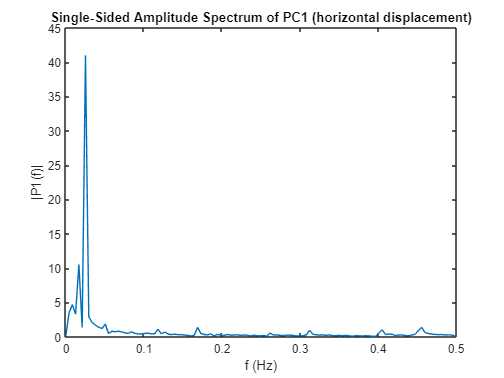

P1_1_Hor(2:end-1) = 2*P1_1_Hor(2:end-1);

f1_Hor = Fs_Hor*(0:(L_Hor/2))/L_Hor;
plot(f1_Hor,P1_1_Hor) 
title('Single-Sided Amplitude Spectrum of PC1 (horizontal displacement)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


P1_1_max_Hor = max(P1_1_Hor)

P1_1_max_Hor = 40.9994

f1_max_Hor = f1_Hor(P1_1_Hor == P1_1_max_Hor)

f1_max_Hor = 0.0253

#### PC2

%%% Modified from fft documentation

P2_2_Hor = abs(f_2_Hor/L_Hor);
P1_2_Hor = P2_2_Hor(1:L_Hor/2+1);

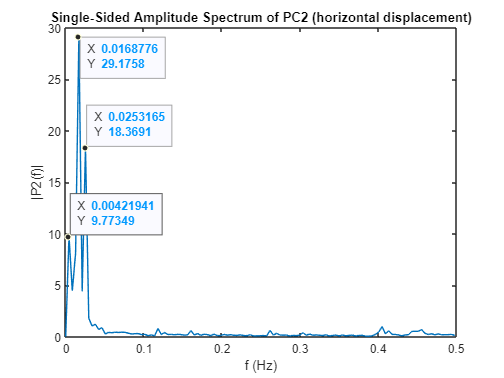

P1_2_Hor(2:end-1) = 2*P1_2_Hor(2:end-1);

f2_Hor = Fs_Hor*(0:(L_Hor/2))/L_Hor;
plot(f2_Hor,P1_2_Hor) 
title('Single-Sided Amplitude Spectrum of PC2 (horizontal displacement)')
xlabel('f (Hz)')
ylabel('|P2(f)|')


P1_2_max_Hor = max(P1_2_Hor)

P1_2_max_Hor = 29.1758

f2_max_Hor = f2_Hor(P1_2_Hor == P1_2_max_Hor)

f2_max_Hor = 0.0169

#### PC3

%%% Modified from fft documentation

P2_3_Hor = abs(f_3_Hor/L_Hor);
P1_3_Hor = P2_3_Hor(1:L_Hor/2+1);

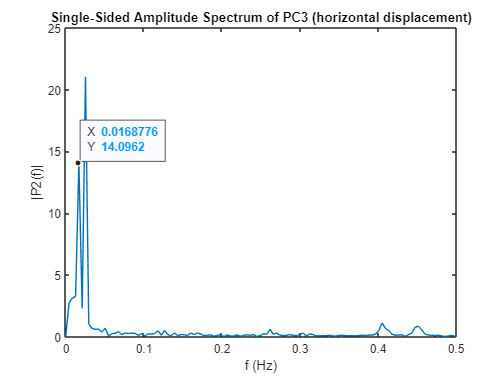

P1_3_Hor(2:end-1) = 2*P1_3_Hor(2:end-1);

f3_Hor = Fs_Hor*(0:(L_Hor/2))/L_Hor;
plot(f3_Hor,P1_3_Hor) 
title('Single-Sided Amplitude Spectrum of PC3 (horizontal displacement)')
xlabel('f (Hz)')
ylabel('|P2(f)|')


P1_3_max_Hor = max(P1_3_Hor)

P1_3_max_Hor = 21.0282

f3_max_Hor = f3_Hor(P1_3_Hor == P1_3_max_Hor)

f3_max_Hor = 0.0253

### Use least square fitting to estimate sine waves for PCs (assuming simple harmonic motion)

#### PC1

%%% Minimise LSE: sum( abs( f(x_k)-y_k )^2 )
%%% Function: f(x) = A*sin(omega_n*x + phi)
xs_Hor = 1:sz_Hor;
LSE_sin_1_Hor = @(n) sum( abs( n(1)*sin(n(2)*xs_Hor + n(3))-Y_Hor(1,:) ).^2 );
n0_1_Hor = [P1_1_max_Hor, f1_max_Hor*2*pi, 0*(pi/180)];
coef_1_Hor = fminsearch(LSE_sin_1_Hor,n0_1_Hor)

coef_1_Hor =    41.6285    0.1563   -0.3875


Error_1_Hor = LSE_sin_1_Hor(coef_1_Hor)

Error_1_Hor = 1.6122e+04

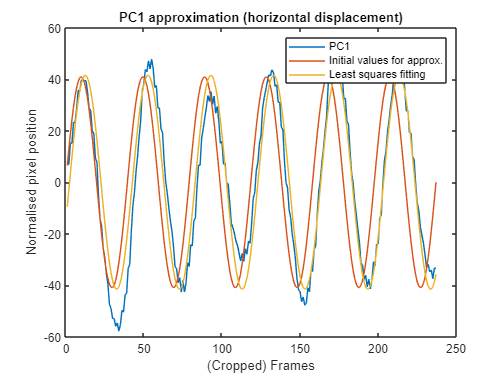


y_1_Hor = coef_1_Hor(1)*sin(coef_1_Hor(2)*xs_Hor + coef_1_Hor(3));
y_1_a_Hor = n0_1_Hor(1)*sin(n0_1_Hor(2)*xs_Hor + n0_1_Hor(3));

plot(Y_Hor(1,:))
title('PC1 approximation (horizontal displacement)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y_1_a_Hor)
plot(y_1_Hor)
legend('PC1','Initial values for approx.', 'Least squares fitting')
hold off

#### PC1 (with multiple sine waves)

%%% Function: f(x) = A_1*sin(omega_n1*x + phi_1) 
%%%                + A_2*sin(omega_n2*x + phi_2)
xs_Hor = 1:sz_Hor;
LSE_sin_1_mult_Hor = @(n) sum( abs( (n(1)*sin(n(2)*xs_Hor + n(3)) ...
                                + n(4)*sin(n(5)*xs_Hor + n(6)) )-Y_Hor(1,:) ).^2 );
n0_1_mult_Hor = [P1_1_max_Hor, f1_max_Hor*2*pi, 90*(pi/180), ...
                 10, 0.0168776*2*pi, 180*(pi/180)];
coef_1_mult_Hor = fminsearch(LSE_sin_1_mult_Hor,n0_1_mult_Hor)

coef_1_mult_Hor =    40.9883    0.1571   -0.4611    9.2748    0.1086    1.4139


Error_1_mult_Hor = LSE_sin_1_mult_Hor(coef_1_mult_Hor)

Error_1_mult_Hor = 6.3548e+03

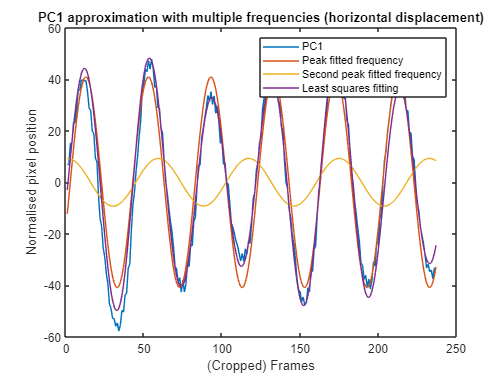


y_1_mult_Hor = coef_1_mult_Hor(1)*sin(coef_1_mult_Hor(2)*xs_Hor + coef_1_mult_Hor(3)) ...
             + coef_1_mult_Hor(4)*sin(coef_1_mult_Hor(5)*xs_Hor + coef_1_mult_Hor(6));
y_1_mult_a_Hor = coef_1_mult_Hor(1)*sin(coef_1_mult_Hor(2)*xs_Hor + coef_1_mult_Hor(3));
y_1_mult_b_Hor = coef_1_mult_Hor(4)*sin(coef_1_mult_Hor(5)*xs_Hor + coef_1_mult_Hor(6));

plot(Y_Hor(1,:))
title('PC1 approximation with multiple frequencies (horizontal displacement)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y_1_mult_a_Hor)
plot(y_1_mult_b_Hor)
plot(y_1_mult_Hor)
legend('PC1','Peak fitted frequency','Second peak fitted frequency', ...
    'Least squares fitting')
hold off

#### PC2

xs_Hor = 1:sz_Hor;
LSE_sin_2_Hor = @(n) sum( abs( n(1)*sin(n(2)*xs_Hor + n(3))-Y_Hor(2,:) ).^2 );
n0_2_Hor = [P1_2_max_Hor, f2_max_Hor*2*pi, 0*(pi/180)];
coef_2_Hor = fminsearch(LSE_sin_2_Hor,n0_2_Hor)

coef_2_Hor =    29.9582    0.1032    2.4310


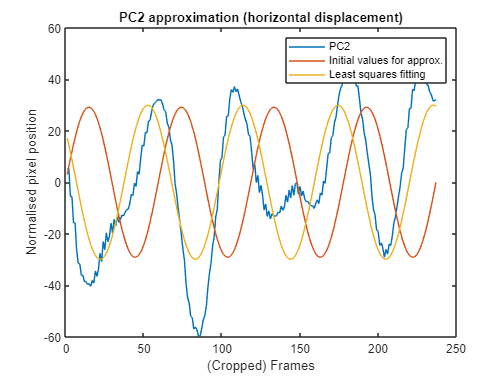


y_2_Hor = coef_2_Hor(1)*sin(coef_2_Hor(2)*xs_Hor + coef_2_Hor(3));
y0_2_Hor = n0_2_Hor(1)*sin(n0_2_Hor(2)*xs_Hor + n0_2_Hor(3));

plot(Y_Hor(2,:))
title('PC2 approximation (horizontal displacement)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y0_2_Hor)
plot(y_2_Hor)
legend('PC2','Initial values for approx.', 'Least squares fitting')
hold off

#### PC2 (with multiple sine waves)

%%% Function: f(x) = A_1*sin(omega_n1*x + phi_1) 
%%%                + A_2*sin(omega_n2*x + phi_2)
%%%                + A_3*sin(omega_n3*x + phi_3)
xs_Hor = 1:sz_Hor;
LSE_sin_2_mult_Hor = @(n) sum( abs( (n(1)*sin(n(2)*xs_Hor + n(3)) ...
                                + n(4)*sin(n(5)*xs_Hor + n(6)) ...
                                + n(7)*sin(n(8)*xs_Hor + n(9)) )-Y_Hor(2,:) ).^2 );
n0_2_mult_Hor = [P1_2_max_Hor, f2_max_Hor*2*pi, 90*(pi/180), ...
                 18, 0.0253165*2*pi, 270*(pi/180), ...
                 10, 0.00421941*2*pi, 90*(pi/180)];
coef_2_mult_Hor = fminsearch(LSE_sin_2_mult_Hor,n0_2_mult_Hor)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 6719.687302 



coef_2_mult_Hor =    29.0216    0.1030    2.3589   17.1224    0.1597    3.6076   12.5833    0.0118    4.9079


Error_2_mult_Hor = LSE_sin_2_mult_Hor(coef_2_mult_Hor)

Error_2_mult_Hor = 6.7197e+03

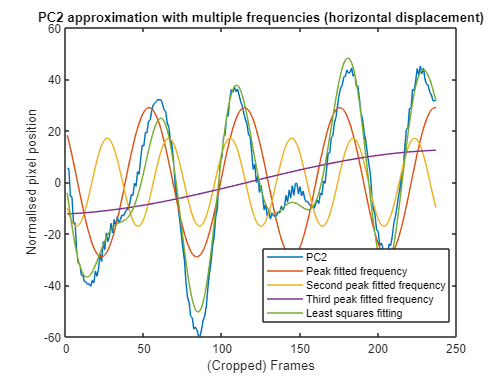


y_2_mult_Hor = coef_2_mult_Hor(1)*sin(coef_2_mult_Hor(2)*xs_Hor + coef_2_mult_Hor(3)) ...
             + coef_2_mult_Hor(4)*sin(coef_2_mult_Hor(5)*xs_Hor + coef_2_mult_Hor(6)) ...
             + coef_2_mult_Hor(7)*sin(coef_2_mult_Hor(8)*xs_Hor + coef_2_mult_Hor(9));
y_2_mult_a_Hor = coef_2_mult_Hor(1)*sin(coef_2_mult_Hor(2)*xs_Hor + coef_2_mult_Hor(3));
y_2_mult_b_Hor = coef_2_mult_Hor(4)*sin(coef_2_mult_Hor(5)*xs_Hor + coef_2_mult_Hor(6));
y_2_mult_c_Hor = coef_2_mult_Hor(7)*sin(coef_2_mult_Hor(8)*xs_Hor + coef_2_mult_Hor(9));

plot(Y_Hor(2,:))
title('PC2 approximation with multiple frequencies (horizontal displacement)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y_2_mult_a_Hor)
plot(y_2_mult_b_Hor)
plot(y_2_mult_c_Hor)
plot(y_2_mult_Hor)
legend('PC2','Peak fitted frequency','Second peak fitted frequency', ...
    'Third peak fitted frequency','Least squares fitting','Location','best')
hold off

#### PC3

xs_Hor = 1:sz_Hor;
LSE_sin_3_Hor = @(n) sum( abs( n(1)*sin(n(2)*xs_Hor + n(3))-Y_Hor(3,:) ).^2 );
n0_3_Hor = [P1_3_max_Hor, f3_max_Hor*2*pi, 0*(pi/180)];
coef_3_Hor = fminsearch(LSE_sin_3_Hor,n0_3_Hor)

coef_3_Hor =    21.3629    0.1567    1.2076


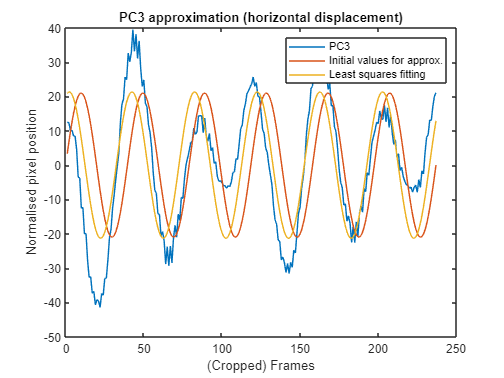


y_3_Hor = coef_3_Hor(1)*sin(coef_3_Hor(2)*xs_Hor + coef_3_Hor(3));
y0_3_Hor = n0_3_Hor(1)*sin(n0_3_Hor(2)*xs_Hor + n0_3_Hor(3));

plot(Y_Hor(3,:))
title('PC3 approximation (horizontal displacement)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y0_3_Hor)
plot(y_3_Hor)
legend('PC3','Initial values for approx.', 'Least squares fitting')
hold off

#### PC3 (with multiple sine waves)

%%% Function: f(x) = A_1*sin(omega_n1*x + phi_1) 
%%%                + A_2*sin(omega_n2*x + phi_2)
xs_Hor = 1:sz_Hor;
LSE_sin_3_mult_Hor = @(n) sum( abs( (n(1)*sin(n(2)*xs_Hor + n(3)) ...
                                + n(4)*sin(n(5)*xs_Hor + n(6)) )-Y_Hor(3,:) ).^2 );
n0_3_mult_Hor = [P1_3_max_Hor, f3_max_Hor*2*pi, 90*(pi/180), ...
                 14, 0.0168776*2*pi, 90*(pi/180)];
coef_3_mult_Hor = fminsearch(LSE_sin_3_mult_Hor,n0_3_mult_Hor)

coef_3_mult_Hor =    21.4830    0.1571    1.1537   13.9203    0.1042    3.0537


Error_3_mult_Hor = LSE_sin_3_mult_Hor(coef_3_mult_Hor)

Error_3_mult_Hor = 4.0079e+03

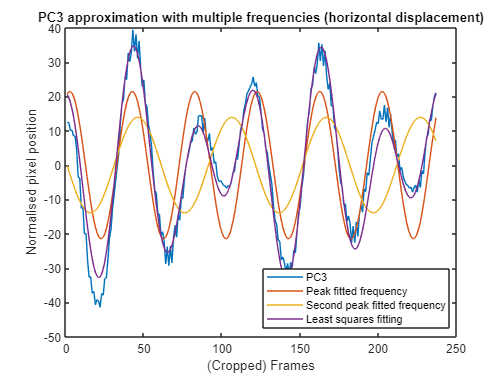


y_3_mult_Hor = coef_3_mult_Hor(1)*sin(coef_3_mult_Hor(2)*xs_Hor + coef_3_mult_Hor(3)) ...
             + coef_3_mult_Hor(4)*sin(coef_3_mult_Hor(5)*xs_Hor + coef_3_mult_Hor(6));
y_3_mult_a_Hor = coef_3_mult_Hor(1)*sin(coef_3_mult_Hor(2)*xs_Hor + coef_3_mult_Hor(3));
y_3_mult_b_Hor = coef_3_mult_Hor(4)*sin(coef_3_mult_Hor(5)*xs_Hor + coef_3_mult_Hor(6));

plot(Y_Hor(3,:))
title('PC3 approximation with multiple frequencies (horizontal displacement)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y_3_mult_a_Hor)
plot(y_3_mult_b_Hor)
plot(y_3_mult_Hor)
legend('PC3','Peak fitted frequency','Second peak fitted frequency', ...
    'Least squares fitting','Location','best')
hold off

## Various functions are here:

### Imports data

function camData = importCamData(Dataset,Camera)

Data_path =join( ['C:' ...
    '\Users' ...
    '\dakin' ...
    '\OneDrive - University College London' ... 
    '\Project Datasets' ...
    '\',Dataset, ... 
    '\',Camera] ); % Change to location of files

camData = load( Data_path );

end



### Shows cropped and uncropped video frame

%%% Shows cropped and uncropped video frame
function [im_1,im_2] = showFrames(frameNum,vidFrame,width,height)

normFrame = vidFrame(:,:,:,frameNum);
im_1 = image(normFrame);

croppedFrame = vidFrame(height,width,:,frameNum);
im_2 = image(croppedFrame);

end



### Finds pixel that corresponds to cap

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d)

if nargin == 4
    d = 10;
elseif nargin == 2
    x = 82;
    y = 198;
end


r = croppedFrame1(end-y,x,1);
g = croppedFrame1(end-y,x,2);
b = croppedFrame1(end-y,x,3);


cap_Pixels = ((croppedFrame(:,:,1) >= r - d) & (croppedFrame(:,:,1) <= r + d)) ...
            &((croppedFrame(:,:,2) >= g - d) & (croppedFrame(:,:,2) <= g + d)) ...
            &((croppedFrame(:,:,3) >= b - d) & (croppedFrame(:,:,3) <= b + d));
end



### Finds the pixels that correspond to the cap using brightness

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixelsBright(croppedFrame,d)

if nargin == 1
    d = 10;
end

br = max( rgb2gray(croppedFrame) );

cap_Pixels = ((croppedFrame(:,:,1) >= br - d) & (croppedFrame(:,:,1) <= br + d)) ...
            &((croppedFrame(:,:,2) >= br - d) & (croppedFrame(:,:,2) <= br + d)) ...
            &((croppedFrame(:,:,3) >= br - d) & (croppedFrame(:,:,3) <= br + d));
end

### Finds the bounds for the cap pixels

%%% Finds the bounds for the cap pixels
function [top,bottom,left,right] = Boundaries(cap_Pixels)

top = 0;
bottom = 0;
left = 0;
right = 0;

sz_row = size(cap_Pixels,1);
for i = 1:sz_row
    findOne = size(find(cap_Pixels(i,:)));
    if findOne(2) ~= 0
        top = sz_row - i;
        break;
    end
end

for i = 1:sz_row
    findOne = size(find(cap_Pixels(end-i,:)));
    if findOne(2) ~= 0
        bottom = i;
        break;
    end
end

sz_col = size(cap_Pixels,2);
for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,i)));
    if findOne(1) ~= 0
        left = i;
        break;
    end
end

for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,end-i)));
    if findOne(1) ~= 0
        right = sz_col - i;
        break;
    end
end

end



### Finds centre from bounds

%%% Finds centre from bounds
function [x,y] = centre(top,bottom,left,right)

y = mean([top,bottom]);
x = mean([left,right]);

end



### Finds centre from averaging the number of pixels

%%% Finds centre from averaging the number of pixels
function [x,y] = centre_avg(cap_Pixels)
[sz_row,sz_col] = size(cap_Pixels);

x = 0;
x_num = 0;
for i = 1:sz_col
    x = x + sum(cap_Pixels(:,i))*i ;
    x_num = x_num + sum(cap_Pixels(:,i)) ;
end
x = x/x_num;

y = 0;
y_num = 0;
for i = 1:sz_row
    y = y + sum(cap_Pixels(i,:))*i ;
    y_num = y_num + sum(cap_Pixels(i,:)) ;
end
y = sz_row - y/y_num;

end



### Gets X and Y data from camera data

%%% Gets X and Y data from camera data
function [X,Y] = getXY(camData,width,height,x,y,d)

if nargin == 5
    d = 10;
elseif nargin == 3
    x = 82;
    y = 198;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);
croppedFrame1 = camData(height,width,:,1);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d);
    
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Gets X and Y data from camera data using brightness

%%% Gets X and Y data from camera data
function [X,Y] = getXYBright(camData,width,height,d)

if nargin == 3
    d = 10;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixelsBright(croppedFrame,d);
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Plots X and Y on the same graph

%%% Plots X and Y on the same graph
function plotXY(X,Y,d,Dataset)

plot(X)
if nargin == 4
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (data = ',Dataset,', d = ',num2str(d),')']);
else
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (d = ',num2str(d),')']);
end
title(title_text)
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y)
legend('X','Y')
hold off

end



